# Hello there !

This is an example, how to use this package code to build a copula-based joint distribution function. 

I used 11 bivariate and 8 trivariate different copula as mentioned in

Najib MK et al., (2021) Quantifying the Joint Distribution of Drought Indicators in Borneo Fire-Prone Area. In: The 4th International Conference on Science & Technology Applications in Climate Change.

and a coming soon article. I suggest you to **read the article** before using this code, in order to understand what is in this code.

If you use this code for your work, please cite this web page and our work above.

[https://github.com/mkhoirun-najiboi/mycopula](https://github.com/mkhoirun-najiboi/mycopula)

## First of all, get your data. 

In this example, I use the data contained in matlab, i.e., the stock returns dataset.

clear;clc
addpath('scr\')

load stockreturns.mat
x = stocks(:,1);
y = stocks(:,2);

## Plot your data

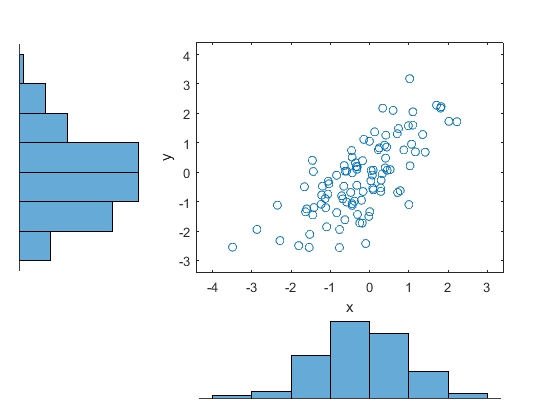

figure;
scatterhist(x,y)

## Fit the univariate marginal distributions of each data

I used three marginal distributions, i.e., Generalized Extreme Value and Lognormal Distribution for continous data, and Negative Binomial Distribution for discrete data.

[Fx,statx] = fitter(x,'gev')

Fx =   GeneralizedExtremeValueDistribution

  Generalized Extreme Value distribution
        k = -0.328924   [-0.432335, -0.225513]
    sigma =   1.07646   [0.930162, 1.24577]
       mu = -0.549162   [-0.77785, -0.320473]


statx = struct with fields:
    distribusi: 'gev'
     keputusan: 0
          pval: 0.9042
        ADstat: 0.3411
             k: -0.3289
         sigma: 1.0765
            mu: -0.5492
         NLogL: 145.5971
           AIC: 297.1942


[Fy,staty] = fitter(y,'gev')

Fy =   GeneralizedExtremeValueDistribution

  Generalized Extreme Value distribution
        k = -0.213617   [-0.350629, -0.0766055]
    sigma =   1.19747   [1.02513, 1.39878]
       mu = -0.668376   [-0.930156, -0.406596]


staty = struct with fields:
    distribusi: 'gev'
     keputusan: 0
          pval: 0.9949
        ADstat: 0.1800
             k: -0.2136
         sigma: 1.1975
            mu: -0.6684
         NLogL: 163.9329
           AIC: 333.8659


Now, you have got the marginal distribution of your data. "keputusan" is 0 meaning that there is no reason to reject the fit distribution, based on the Anderson-Darling test with 5% alpha.

## Transform your data

Transform your data to uniform~(0,1) using fitted marginal distribution.

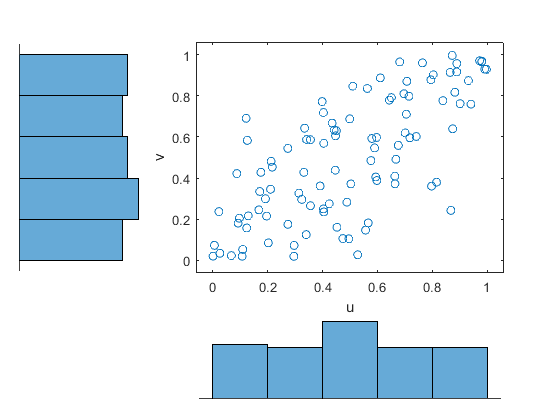

u = cdf(Fx,x);
v = cdf(Fy,y);
scatterhist(u,v)

## Get your fittest copula

stat = mycopula([u,v]);

ans = 11×6 table
      famili      param1        param2          Dn         RMSE        AIC  
    __________    _______    ____________    ________    ________    _______

    'Gaussian'    0.72065    []              0.054113    0.020917    -71.239
    't'           0.72057    [1.3590e+07]    0.054122     0.02092    -69.239
    'BB8'          5.2154    [    0.7448]    0.046991    0.017162    -66.681
    'Frank'        6.0292    []              0.057931     0.02152    -65.961
    'Galambos'      1.195    []              0.048434    0.019472    -65.558
    'Gumbel'       1.9136    []              0.048723    0.019405    -65.307
    'BB1'         0.18977    [    1.7648]    0.051983    0.020486     -64.65
    'BB6'               1    [    1.9136]    0.048723    0.019405    -63.307
    'BB7

## Plot your copula distribution

For 1-parameter copula:

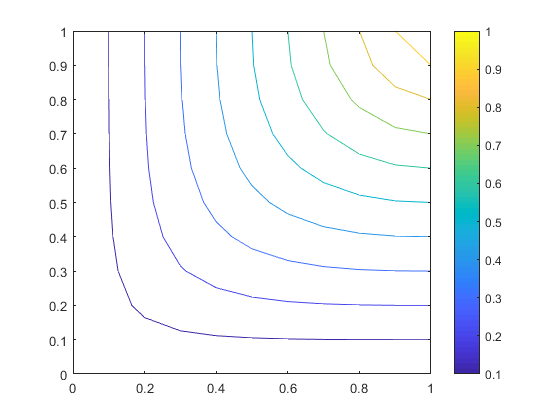

x1 = 0:0.1:1;
y1 = 0:0.1:1;
[u1,v1] = meshgrid(x1,y1); 
Cx = cdfcopula('Gaussian',[u1(:),v1(:)],0.7206);
Cx = reshape(Cx,[length(x1),length(y1)]);
Cx = Cx';

contour(x1,y1,Cx);colorbar

For 2-parameter copula:

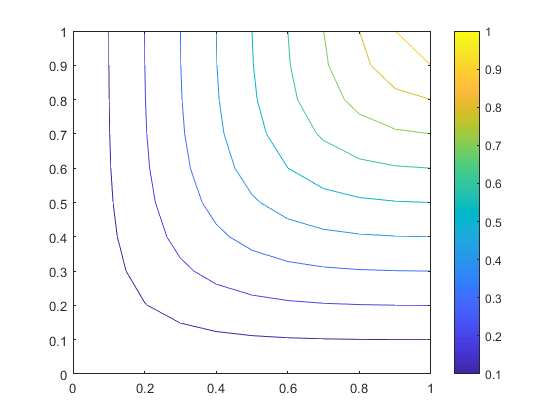

x1 = 0:0.1:1;
y1 = 0:0.1:1;
[u1,v1] = meshgrid(x1,y1); 
Cx = cdfcopula('BB8',[u1(:),v1(:)],5.2154,0.7448);
Cx = reshape(Cx,[length(x1),length(y1)]);
Cx = Cx';

contour(x1,y1,Cx);colorbar;

## Plot your copula density with transformed data

For 1-parameter copula:

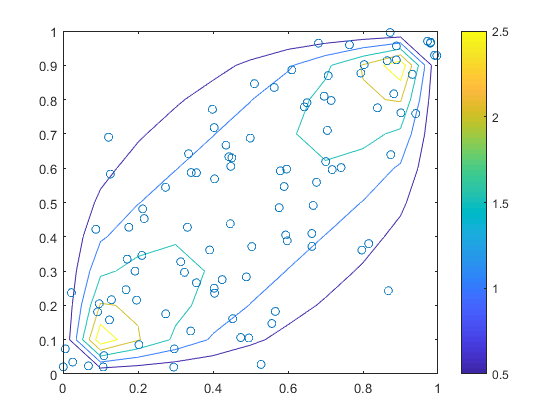

x1 = 0:0.1:1;
y1 = 0:0.1:1;
[u1,v1] = meshgrid(x1,y1); 
cx = pdfcopula('Gaussian',[u1(:),v1(:)],0.7206);
cx = reshape(cx,[length(x1),length(y1)]);
cx = cx';

figure;
contour(x1,y1,cx);colorbar
hold on 
scatter(u,v)

## Plot your copula density with actual data

For 1-parameter copula:

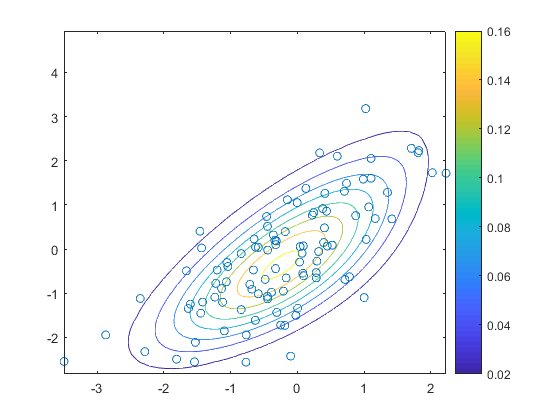

x1 = 0:0.01:1;
y1 = 0:0.01:1;
[u1,v1] = meshgrid(x1,y1); 
cx = pdfcopula('Gaussian',[u1(:),v1(:)],0.7206);
cx = reshape(cx,[length(x1),length(y1)]);
cx = cx';
x1 = icdf(Fx,u1);f1 = pdf(Fx,x1);
x2 = icdf(Fy,v1);f2 = pdf(Fy,x2);
fx = f1.*f2.*cx;

figure;
contour(x1,x2,fx);colorbar
hold on 
scatter(x,y)